# Practice Problems

# Contour Extraction I

In this problem, you will use morphological erosion to extract the contours or the circular boundaries of coins in the given image.

I = imread("coins.png");                        % Read a binary image
figure;
imshow(I)        

As a first step, you must convert the grayscale coins image into a binary image, such that the brighter objects in the foreground (coins in this case) become completely bright (`1`) and the darker background becomes completely dark (`0`). To do this, you will threshold the gray intensities of the image.

a. **Task.** Use the slider to adjust the scalar threshold level between `0` and `255`. Try and ensure that all parts of the image containing coins are converted to white (`logical 1`) as best as possible.

BWCoins = I >189;        % Relational operation returns a logical output (binary image)
imshow(BWCoins);
title("Segmentation")

This is your segmentation result. A good segmentation will set you up to get more accurate coin boundaries at the end.

b.** Task. **Replace the code in the edit field below to create a disk-shaped structuring element with a radius of `1`. Use the `strel` function.

SE = false(3);

c.** Task.** Replace the code in the edit field below to erode the segmentation output `BWCoins` using the structuring element `SE`. Use the `imerode` function.

BWCoinsEroded = false(size(BWCoins));

d.** Task.** Replace the code in the edit field below to get the coins' boundaries by combining the binary images (`BWCoins` and `BWCoinEroded`) using the appropriate logical operators.This should give you a thin boundary surrounding the coins.

BWCoinsContour = false(size(BWCoins));
imshow(BWCoinsContour)

Notice how one of the coins has contours inside it because of incomplete segmentation in step a.

# Contour Extraction II

In Contour Extraction I, you applied basic morphology and logical operations to get the boundaries of coins. The first step to do this was to binarize the image to get the coins as foreground (white) and everything else as background (black).

a. Read the image and apply a threshold to the gray intensities to get a binary mask of coins.

I = imread("coins.png");                      % Read a binary image
figure;
imshow(I)
BWCoins = I > 85;      % Relational operation returns a logical output (binary image)
imshow(BWCoins)                                     

b.** Task. **To "close" any small holes in the coins (foreground), apply the closing operation to `BWCoins` with a disk of radius `1` `o`r `2`. Replace the code in the edit fields below with the appropriate function calls.

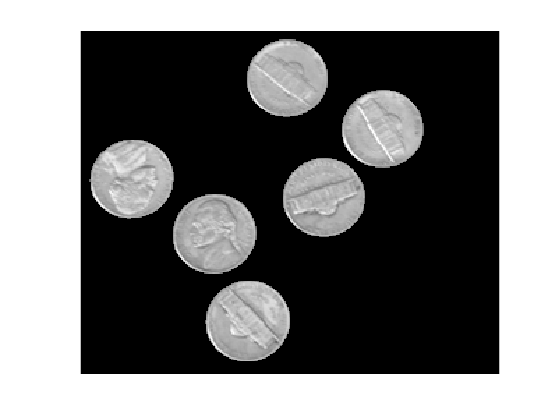

SE = false(2);                        % Create a structuring element
BWCoinsClosed = false(size(BWCoins));             % Closing

imshow(BWCoinsClosed)

c. **Task. **To remove any tiny specks of white in the black background, apply the opening operation to `BWCoinsClosed` with a disk of radius `1` `o`r `2`. Replace the code in the edit fields below with the appropriate function calls.

SE = strel("disk",1);                        % Create a structuring element
BWCoinsOpened = imopen(BWCoinsClosed,SE);             % Opening
imshow(BWCoinsOpened)

d. Extract the contours by first eroding `BWCoinsClosed` with a tiny disk element and then excluding the eroded result from `BWCoinsClosed`.

SE = strel("disk",1)                              % Create a structuring element
BWCoinsEroded = imerode(BWCoinsOpened,SE);        % Erosion
imshow(BWCoinsEroded)
               
BWContour = BWCoinsOpened & ~BWCoinsEroded;       % Retain the boundaries of the coins by excluding the eroded coins from the closed coins
imshow(BWContour)

***Reflect***

- *Depending on the scalar threshold used for segmenting the coins, your image may have either holes or noisy specks or both. Try increasing or decreasing the value using the slider to observe the effects of opening and closing operations in each case.*

# Identifying Nickels

In this exercise, you will use morphological and logical operations to separate the nickels from the dimes in `coins.png`. 

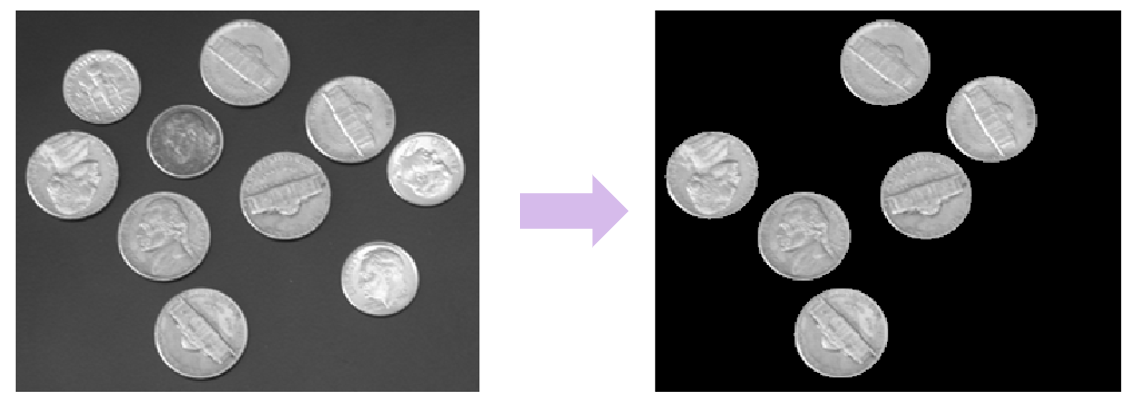

 ***Reflect***

- *Before following the instructions given below for this exercise, think of how you might approach this problem using morphological operations. What are the steps you will use to separate the nickels?*

a. Measure the sizes (radii) of the two types of coins in the image. Select an integer-valued radius for a disk-shaped structuring element in between these two. 

**Task. **Click** Measure coins** button**.** A small window containing the image and several tools will open. Use the **Distance** tool   to measure the approximate diameters of the two different coins. You can zoom in and out to get a better resolution. Enter the values in the next section.

I = imread("coins.png");
imageViewer(I)

Use this section to enter the measurements from step a, choose the size of the structuring element for the next step, and validate your estimation.

radiusSmall = 0/2
radiusBig = 0/2
radiusSE = 0;

disp("Use the dropdown to check if radius is correct")

b.** Task.** Replace the code in the edit fields below to apply morphological opening to `BWCoins` with the disk-shaped structuring element of radius `radiusSE` determined in step a.

I = imread("coins.png");
BWCoins = I > 100;

SE = false(3);          
BWCoinsOpened = false(size(BWCoins));

imshow(BWCoinsOpened)

c.** Task. **Replace the code in the edit fields below to dilate `BWCoinsOpened` with a small disk-shaped structuring element. Pick a radius such that the foreground objects (white pixels) in the dilated image will wholly encompass the regions containing nickels without any of the shapes overlapping.

SE = false(3);
BWCoinsDilated = false(size(BWCoins));
imshow(BWCoinsDilated)

d.** Task. **Use a logical operator to combine `BWCoinsDilated` (result from step d) with `BWCoins` (the segmented coins) to retain the nickels (large circles) and eliminate the dimes (small circles).

BWNickels = false(size(BWCoins));
imshow(BWNickels)

e. Extract the coins from the original image. The elements in the original grayscale image corresponding to the `1`s in `BWNickels` will be retained, while all other parts of the original image will be set to `0.`

nickels = I .* uint8(BWNickels);
imshow(nickels)